clear all;
close all;

model = "basys";
size_device = 33;

size_response_raw = 1023;
size_response_ecc = 171;


## TERO-4

prefix = "tero_4";
limit = 50;

references_tero_4_raw = zeros(size_response_raw, size_device);

inter_uniformities_tero_4_raw = zeros(1, size_device);

inter_reliabilities_tero_4_raw = zeros(1, size_device);
for i=1:size_device
    raw_data = readmatrix(model+"_"+prefix+'_raw_'+string(limit)+"_device_"+string(i)+'.csv');
    [references_tero_4_raw(:,i), ~, ~, inter_uniformities_tero_4_raw(i), inter_reliabilities_tero_4_raw(i), ~, ~] = intra_device_analysis_fn(raw_data);
end

bit_aliasing_tero_4 = bit_aliasing_fn(references_tero_4_raw);
uniqueness_tero_4 = uniqueness_fn(references_tero_4_raw);

### Uniformities

inter_average_uniformity_raw = mean(inter_uniformities_tero_4_raw)

inter_average_uniformity_raw = 8.0832

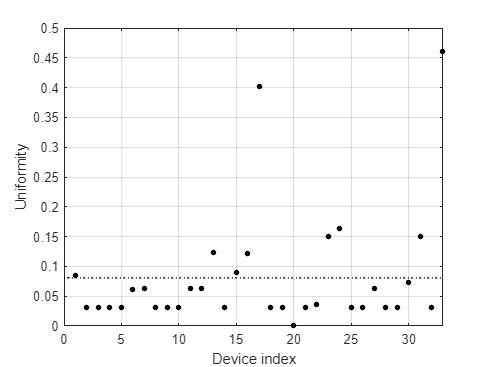



fig_tero_4_uni = figure;
p = plot(1:size_device, inter_uniformities_tero_4_raw./100,'.'); hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
hline = refline([0 inter_average_uniformity_raw/100]);
hline.Color = 'black';
hline.LineStyle = ':';
xlabel("Device index");
ylabel("Uniformity");
xlim([0 size_device]);
grid on;

### Reliabilities

inter_average_reliabilities_raw = mean(inter_reliabilities_tero_4_raw)

inter_average_reliabilities_raw = 99.7588

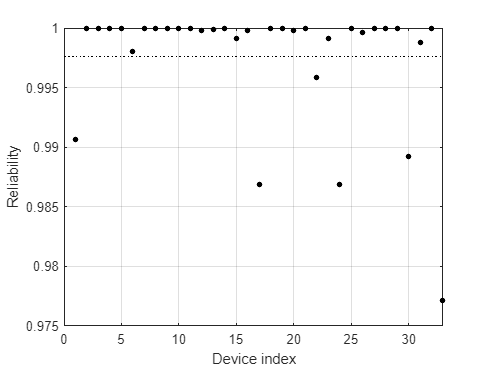


fig_tero_4_relia = figure;
p = plot(1:size_device, inter_reliabilities_tero_4_raw./100,'.'); hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;hline = refline([0 inter_average_reliabilities_raw/100]);
hline.Color = 'black';
hline.LineStyle = ':';
xlabel("Device index");
ylabel("Reliability");
xlim([0 size_device]);
grid on;

### Bit Aliasing & Uniqueness

average_bit_aliasing = mean(bit_aliasing_tero_4)

average_bit_aliasing = 8.0393

uniqueness_tero_4

uniqueness_tero_4 = 8.2774

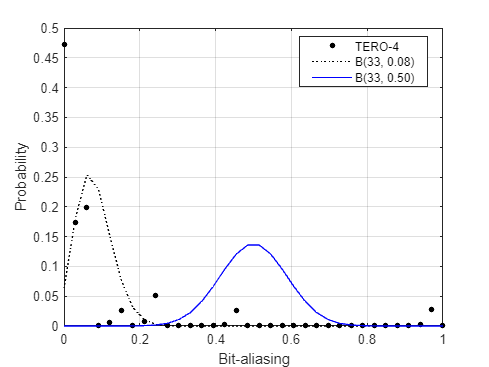


fig_tero_4_alia = figure;


[N, edges] = histcounts(bit_aliasing_tero_4, size_device +1, 'BinLimits',[0,100], 'Normalization','probability');
binormal = binopdf(0:size_device, 33, 0.5);
binormal_offset = binopdf(0:size_device, 33, average_bit_aliasing/100);
p = plot(uni_value, N, '.'); hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;

p = plot(uni_value, binormal_offset, ':'); hold on;
p.Color = 'black';
p = plot(uni_value, binormal); hold on;
p.Color = 'blue';
xlabel("Bit-aliasing");
ylabel("Probability");
legend("TERO-4","B(33, "+string(round(average_bit_aliasing/100,2))+")","B(33, 0.50)");
grid on;
legend("Position", [0.59451,0.75372,0.29852,0.15819])

## TERO-8

prefix = "tero_8";
limit = 50;

references_tero_8_raw = zeros(size_response_raw, size_device);

inter_uniformities_tero_8_raw = zeros(1, size_device);
inter_uniformities_tero_8_raw_crop = zeros(1, size_device);
inter_uniformities_tero_8_ecc = zeros(1, size_device);

inter_reliabilities_tero_8_raw = zeros(1, size_device);
inter_reliabilities_tero_8_raw_crop = zeros(1, size_device);
inter_reliabilities_tero_8_ecc = zeros(1, size_device);

for i=1:size_device

    raw_data = readmatrix(model+"_"+prefix+'_raw_'+string(limit)+"_device_"+string(i)+'.csv');
    [references_tero_8_raw(:,i), ~, ~, inter_uniformities_tero_8_raw(i), inter_reliabilities_tero_8_raw(i), ~, ~] = intra_device_analysis_fn(raw_data);
    
    ecc_data = readmatrix(model+"_"+prefix+'_ecc_'+string(limit)+"_device_"+string(i)+'.csv');
        
    [~, ~, ~, inter_uniformities_tero_8_ecc(i), inter_reliabilities_tero_8_ecc(i), ~, ~] = intra_device_analysis_fn(ecc_data);
    
    croped_data = raw_data(:,1:size_response_ecc);
        
    [size_sample_raw_croped, size_response_raw_croped] = size(croped_data);
    [~, ~, ~, inter_uniformities_tero_8_raw_crop(i), inter_reliabilities_tero_8_raw_crop(i), ~, hd_intra] = intra_device_analysis_fn(croped_data);
end

bit_aliasing_tero_8 = bit_aliasing_fn(references_tero_8_raw);
uniqueness_tero_8 = uniqueness_fn(references_tero_8_raw);

### Uniformities

inter_average_uniformity_raw = mean(inter_uniformities_tero_8_raw)

inter_average_uniformity_raw = 53.3949

inter_average_uniformity_raw_crop = mean(inter_uniformities_tero_8_raw_crop)

inter_average_uniformity_raw_crop = 53.4411

inter_average_uniformity_ecc = mean(inter_uniformities_tero_8_ecc)

inter_average_uniformity_ecc = 53.5457

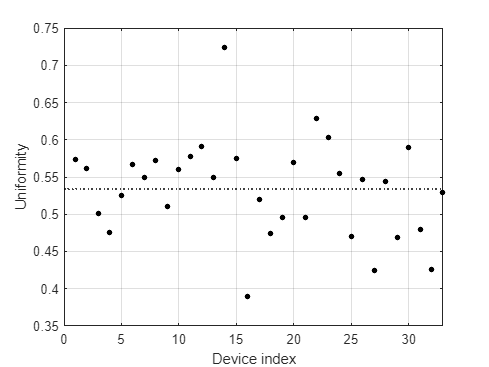


fig_tero_8_uni = figure;
p = plot(1:size_device, inter_uniformities_tero_8_raw./100,'.'); hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;
hline = refline([0 inter_average_uniformity_raw/100]);
hline.Color = 'black';
hline.LineStyle = ':';
grid on;
xlabel("Device index");
ylabel("Uniformity");
xlim([0 size_device]);

### Reliabilities

inter_average_reliabilities_raw = mean(inter_reliabilities_tero_8_raw)

inter_average_reliabilities_raw = 97.6336

inter_average_reliabilities_raw_crop = mean(inter_reliabilities_tero_8_raw_crop)

inter_average_reliabilities_raw_crop = 97.7076

inter_average_reliabilities_ecc = mean(inter_reliabilities_tero_8_ecc)

inter_average_reliabilities_ecc = 99.9018

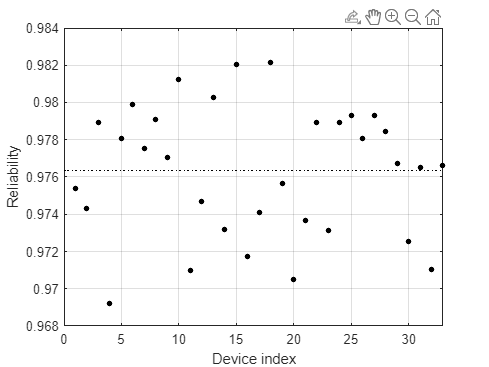


fig_tero_8_relia = figure; 
p = plot(1:size_device, inter_reliabilities_tero_8_raw./100,'.'); hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;hline = refline([0 inter_average_reliabilities_raw/100]);
hline.Color = 'black';
hline.LineStyle = ':';
grid on;
xlabel("Device index");
ylabel("Reliability");
xlim([0 size_device]);

### Bit Aliasing & Uniqueness

average_bit_aliasing = mean(bit_aliasing_tero_8)

average_bit_aliasing = 53.4939

uniqueness_tero_8

uniqueness_tero_8 = 49.4242

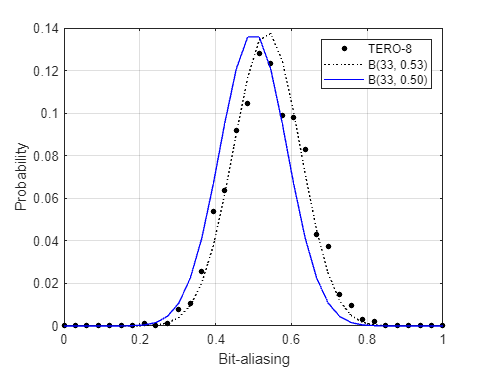


uni_value = 0:1/size_device:1;

[N, edges] = histcounts(bit_aliasing_tero_8, size_device +1, 'BinLimits',[0,100], 'Normalization','probability');
binormal = binopdf(0:size_device, 33, 0.5);
binormal_offset = binopdf(0:size_device, 33, average_bit_aliasing/100);
fig_tero_8_alia = figure;
p = plot(uni_value, N, '.'); hold on;
p.Color = 'black';
p.MarkerFaceColor = 'black';
p.MarkerSize = 12;

p = plot(uni_value, binormal_offset, ':'); hold on;
p.Color = 'black';
p = plot(uni_value, binormal); hold on;
p.Color = 'blue';
xlabel("Bit-aliasing");
ylabel("Probability");
legend("TERO-8","B(33, "+string(round(average_bit_aliasing/100,2))+")","B(33, 0.50)" );
grid on;

saveas(fig_tero_4_uni, "tero_4_inter_uniformities.png");

saveas(fig_tero_4_relia, "tero_4_inter_reliabilities.png");

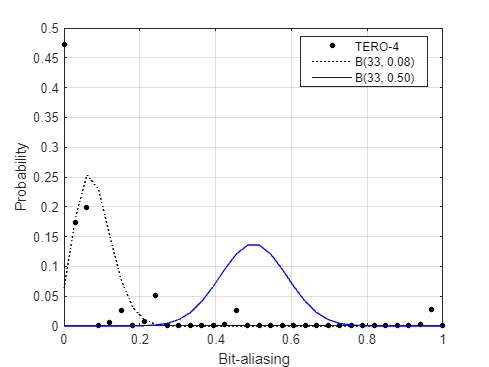

saveas(fig_tero_4_alia, "tero_4_inter_aliasing.png");

saveas(fig_tero_8_uni, "tero_8_inter_uniformities.png");

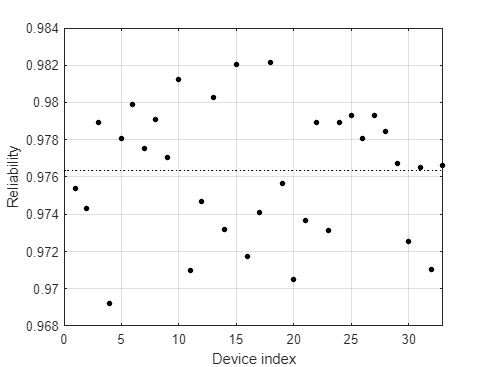

saveas(fig_tero_8_relia, "tero_8_inter_reliabilities.png");

saveas(fig_tero_8_alia, "tero_8_inter_aliasing.png");